clear;
limit=200;
A = [1,0,1,0,1,0];
n= length(A);
lb=[40,0,50,0,10,0];
ub=[60,1000,70,1000,30,1000];
intlimit=[1,3,5];


Single objective optimization:
6 Variable(s)
3 Integer variable(s)
6 Nonlinear inequality constraint(s)
1 Linear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              800        1.49e-05           1.663        0
    2             1170        1.49e-05            1.06        1
    3             1540        1.49e-05           0.654        2
    4             1910        1.49e-05          0.4477        3
    5             2280        1.49e-05          0.2381        4
    6             2650        1.49e-05          0.1818        5
    7             3020        1.49e-05           0.109        6
    8             3390        1.49e-05         0.09249        7
    9             3760          -84.55          -

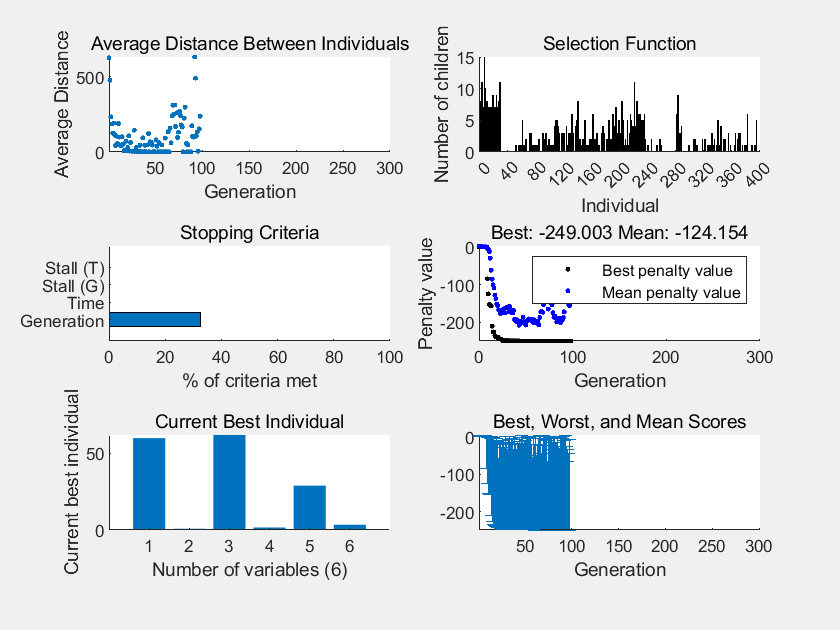

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


% 设置非默认求解器选项
options = optimoptions("ga","SelectionFcn","selectiontournament",...
    "PopulationSize",400,"MaxGenerations",300,"CrossoverFraction",0.7,...
    "CreationFcn","gacreationuniformint","EliteCount",30,"Display","iter",...
    "PlotFcn",["gaplotdistance","gaplotselection","gaplotstopping",...
    "gaplotbestf","gaplotbestindiv","gaplotrange"]);

% 求解
[solution,objectiveValue] = ga(@three_func,n,A,limit,[],[],lb,ub,@three_con,...
    intlimit,options);


% 清除变量
clearvars options
maxvalue = objectiveValue;